# Lab 7 - Surrogate Modeling

Jared Ham

**Task 1: Response Surface Modeling (RSM)**

Given a computationally intensive model, run a discrete amount of simulations and fit a surface to the outputs to allow quicker querying of the model. 

We can call the intensive model using the following the code

x = [1,1];
y = giant_CFD_code(x)

y = 3.2333

Before running the model and fitting to a surface a data set needs to be created in the domain of:


$$\begin{array}{l}
-2\le x_1 \le 2\\
-1\le x_2 \le 1
\end{array}$$


With the following constraints:

70% used for training

15% used for validation (Not neccessary for RSM, but will be for neural network).

15%(30% for RSM) used for testing

n_x1 = 10; %number of x1 data points
n_x2 = 10; % number of x2 data points

x1 = linspace(-2, 2, n_x1);
x2 = linspace(-1, 1, n_x2);

X_training = zeros(floor(n_x1*n_x2 * 0.7), 2);
X_validate = zeros(floor(n_x1 * n_x2*0.2),2);
Y_training = zeros(floor(0.6 * n_x1 * n_x2) , 1);
Y_validate = zeros(floor(n_x1 * n_x2*0.2),1);

X_training_index = 1;
X_validate_index = 1;
Y_traning_index = 1;
Y_validate_index = 1;
for i = 1:length(x1)
    for j = 1:length(x2)
        
        if(rand < 0.7)
            %this will be used in the training set
            Y_training(Y_traning_index) = giant_CFD_code([x1(i), x2(j)]);
            Y_traning_index = Y_traning_index + 1;
            
            X_training(X_training_index, 1) = x1(i);
            X_training(X_training_index, 2) = x2(j);
            X_training_index = X_training_index + 1;
        else
            %this set will be used for validation
            Y_validate(Y_validate_index) = giant_CFD_code([x1(i), x2(j)]);
            Y_validate_index = Y_validate_index + 1;
            
            X_validate(X_validate_index, 1) = x1(i);
            X_validate(X_validate_index, 2) = x2(j);
            X_validate_index = X_validate_index + 1;
        end
        
        
    end
end

Now that we have a training set and a validation set. Let's fit a response surface of the following form using MatLab's rstool


$$y=\beta_1 +\beta_2 x_1 +\beta_3 x_2 +\beta_4 x_1 x_2 +\beta_5 x_1^2 +\beta_6 x_2^2$$


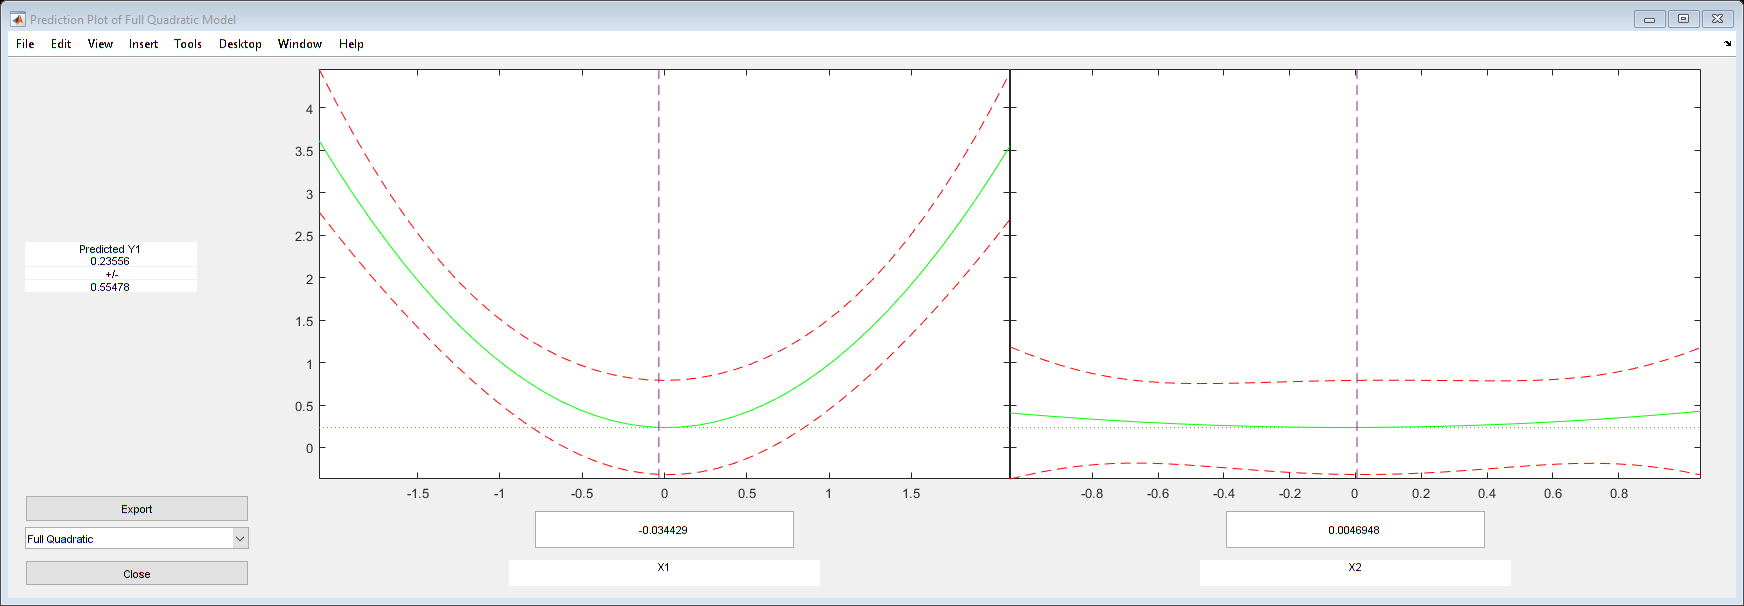

rstool(X_training, Y, 'quadratic')